# Improving Predictive Models

## 3. Reducing Predictors

### 3.1. Feature transformation

Use PCA to reduce the number of predictors in a Naive Bayes classifier.

load heartdisease
HD = heartdataNum.HeartDisease; % Extract the response variable
numdata = heartdataNum{:,1:end-1}; % Extract the numeric predictors as an array
vars = heartdataNum.Properties.VariableNames(1:end-1); % Extract the predictor names

Perform PCA

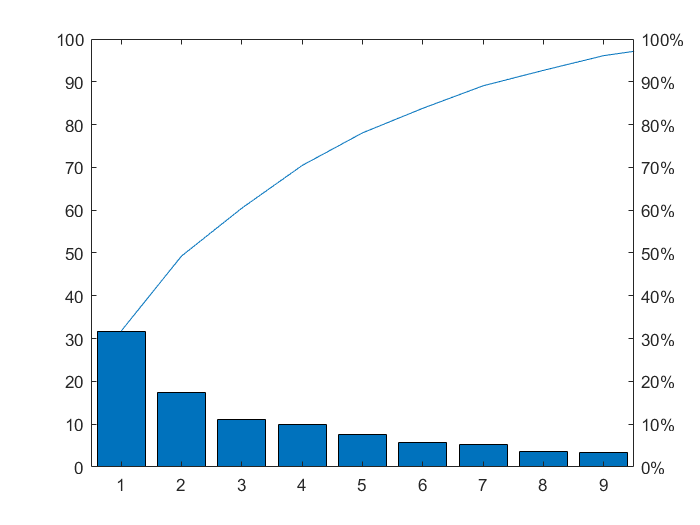

[pcs,scrs,~,~,pexp] = pca(numdata);
pareto(pexp) % You can find that the first eight principal components explain over 90% of variance

Fit a Naive Bayes Model on the reduced data

rng(1234)
printCom8 = scrs(:,1:8) % Use the first eight principal components

printCom8 =     0.1105    0.1089   -0.4042    0.0212    0.2028   -0.0537   -0.0350    0.0884
   -0.0809    0.0750   -0.4009    0.1968    0.0474    0.1480    0.0543    0.0716
   -0.0765   -0.2391   -0.0837    0.0736    0.2836   -0.0581    0.0226    0.1745
    0.5920    0.1121   -0.1163   -0.4166    0.4789    0.0913   -0.2056   -0.0622
    0.2090   -0.0348    0.0836   -0.2165    0.0487    0.0313    0.1505   -0.1157
    0.5692   -0.0778   -0.1129    0.1249    0.2041    0.0019   -0.0195    0.0574
   -0.2675    0.2025   -0.0107   -0.0920    0.3983    0.0359    0.0390    0.1059
    0.1965    0.0043    0.1503    0.1882    0.0553    0.1812   -0.1817    0.1150
   -0.0323   -0.0352    0.0026    0.1261    0.1574    0.1868    0.3468    0.1598
   -0.2570    0.3158    0.0590   -0.2898    0.1685   -0.1400    0.1123    0.2013


part = cvpartition(HD,'KFold',10);

% Fit and evaluate the model on the full dataset.
mdlFull = fitcnb(numdata,HD,'DistributionNames',"kernel",'CVPartition',part);
fullDataLoss = kfoldLoss(mdlFull)

fullDataLoss = 0.2740


% Fit and evaluate the model on the reduced dataset.
mdlReduced = fitcnb(printCom8,HD,'DistributionNames','kernel','CVPartition',part);
reduceDataLoss = kfoldLoss(mdlReduced)

reduceDataLoss = 0.2740

Visualize the relationship between the variables and the principal components

- biplot 

- heatmap (useful) - very useful

- parallelcoords 

- factor analysis

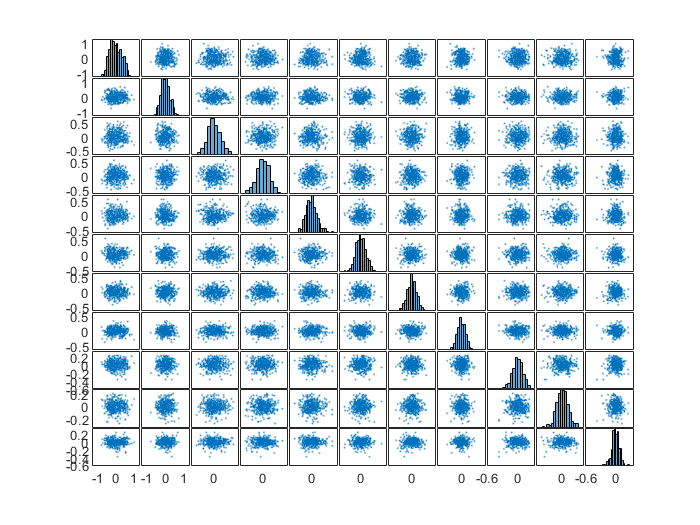

% Verify that the principal components are uncorrelated
%figure
%plotmatrix(scrs)

% 1.Visualize the relationship using biplot function
figure 

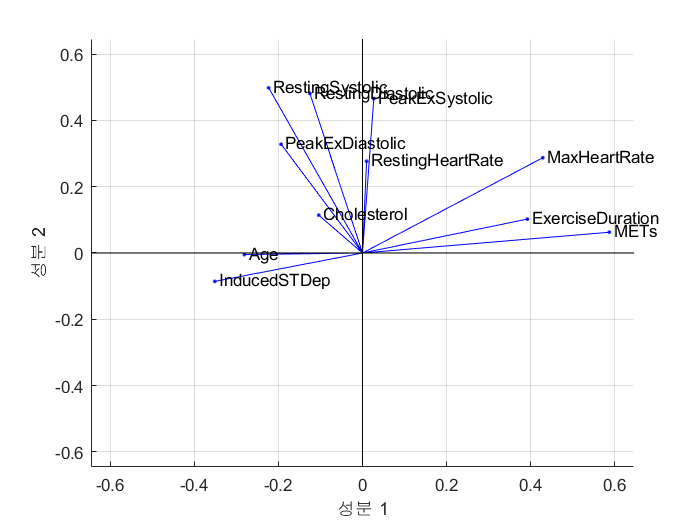

biplot(pcs(:,1:2),'VarLabels',vars)


% 2.Visualize the relationship using heatmap function - important

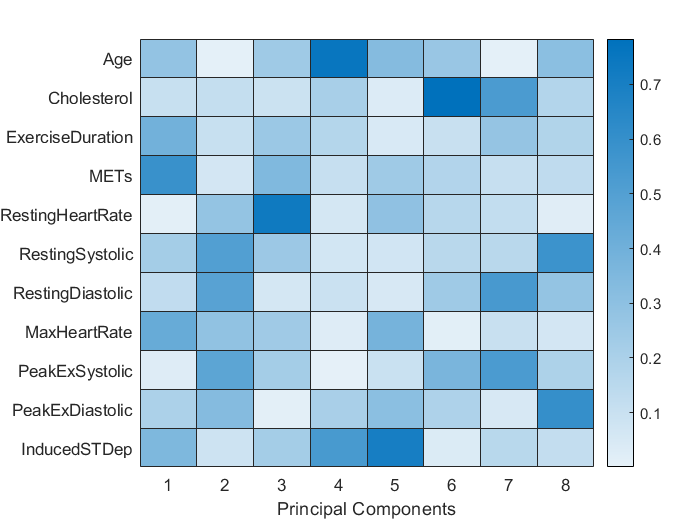

figure
heatmap(abs(pcs(:,1:8)),'YDisplayLabels',vars)
xlabel('Principal Components')

% 3. Visualize predictive power of the principal components
figure

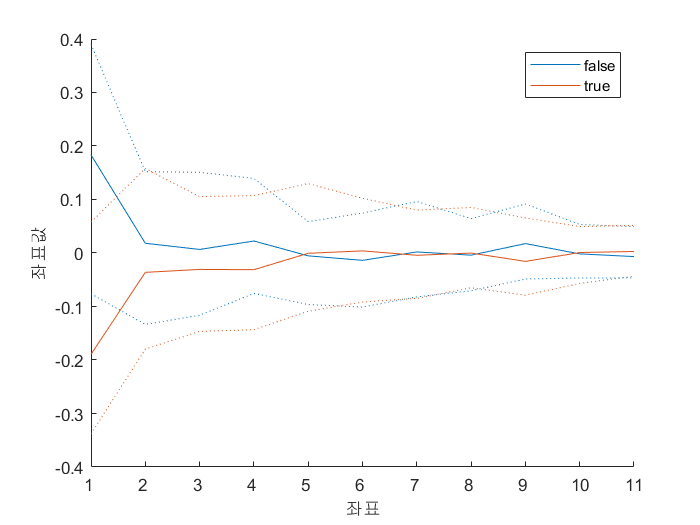

parallelcoords(scrs,'Group',HD,'Quantile',0.25)


% 4. Factor Analysis

[Lambda,Psi,~,~,E] = factoran(numdata,6);
heatmap(abs(Lambda),'YDisplayLabels',vars)

### 3.2. Feature Selection

1. Built-in feature selection for decision tree models

open('treeselect.mlx')

**2. Sequential Feature Selection (IMPORTANT!)**

Perform sequential feature selection on the heart disease data for Naive Bayes and SVM classifiers.

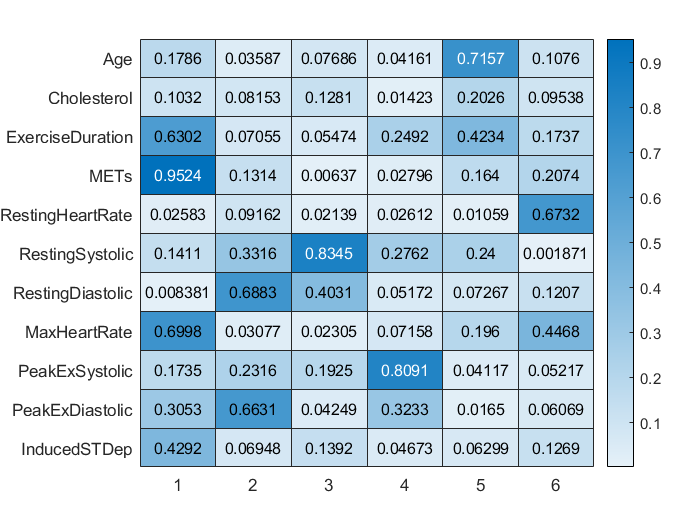

rng(1234)

part = cvpartition(HD,'KFold',10);

Sequential feature selection on a Naive Bayes classifier.

rng(1234)
tokeep_nb = sequentialfs(@errorNB,numdata,HD,'cv',part);
vars(tokeep_nb)

Compare the results with the full dataset.

% Naive Bayes with the full data set.
ndlFull = fitcnb(numdata,HD,'DistributionNames',"kernel",'CVPartition',part)
fullDataLoss = kfoldLoss(ndlFull)

% Naive Bayes with the selected predictors.
numdataSelectedNB = numdata(:,tokeep_nb)
ndlSelected = fitcnb(numdataSelectedNB,HD,'DistributionNames','kernel','CVPartition',part);

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 


error = 22

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 


error = 25

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 


error = 24

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 


error = 26

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 


error = 22

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 22

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 


error = 23

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 22

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 


error = 5

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 22

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 


error = 22

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 


error = 22

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 24

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 21

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 20

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'}
    DistributionParameters: {2×1 cell}
                    Kernel: {'normal'}
                   Support: {'unbounded'}
                     Width: [2×1 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 


error = 19

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 6

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {2×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [2×2 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 6

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 18

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×3 cell}
                    Kernel: {'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×3 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 6

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 6

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 384
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

mdlnb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 385
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×4 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2×4 double]


  Properties, Methods


ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

selectedDataLoss = kfoldLoss(ndlSelected)

ans = 1×3 cell 배열
    {'Age'}    {'MaxHeartRate'}    {'InducedSTDep'}


Sequential feature selection on a SVM classifier.

rng(1234)

ndlFull =   ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'}
           ResponseName: 'Y'
        NumObservations: 427
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [false    true]
         ScoreTransform: 'none'


  Properties, Methods


tokeep_svm = sequentialfs(@errorSVM,numdata,HD,'cv',part)

fullDataLoss = 0.2740

vars(tokeep_svm)


Compare the results with the full data set.

rng(1234)

numdataSelectedNB =     0.7083    0.6090    0.4107
    0.7917    0.2932    0.2679
    0.7917    0.4511    0.4643
    0.1667    0.8872    0.6250
    0.2500    0.7744    0.2500
    0.5625    0.8195    0.1429
    0.6875    0.6842    0.6429
    0.5833    0.7068    0.1071
    0.7083    0.5865    0.2500
    0.5000    0.6466    0.5536


% SVM with full data set.
ndlFull = fitcsvm(numdata,HD,'CVPartition',part);

selectedDataLoss = 0.2670

fullDataLoss = kfoldLoss(ndlFull)

% SVM with the selected predictors.
numdataSelectedSVM = numdata(:,tokeep_svm);
ndlSelected = fitcsvm(numdataSelectedSVM,HD,'CVPartition',part);
selectedDataLoss = kfoldLoss(ndlSelected)

tokeep_svm = 1×11 logical 배열
   0   0   0   0   0   0   1   1   0   0   0


ans = 1×2 cell 배열
    {'RestingDiastolic'}    {'MaxHeartRate'}


Callback function: errorNB function returns the number of inaccurate predictions for `ytest` by a Naive Bayes classifier.

function error = errorNB(Xtrain,ytrain,Xtest,ytest)
mdlnb = fitcnb(Xtrain , ytrain,"DistributionNames","kernel")
ypred = predict(mdlnb,Xtest)
error = nnz(ypred ~= ytest)

fullDataLoss = 0.2787

end


Callback function: errorSVM function returns the number of inaccurate predictions for `ytest` by a SVM classifier.

function error = errorSVM(Xtrain,ytrain,Xtest,ytest)
mdlsvm = fitcsvm(Xtrain,ytrain);
ypred = predict(mdlsvm,Xtest);

selectedDataLoss = 0.2740

error = nnz(ypred ~= ytest);
end
